# Does Earthquake Frequency have a Seasonal Variation?

*Dr. Eric S. Wright*

*The University of Montana Western*

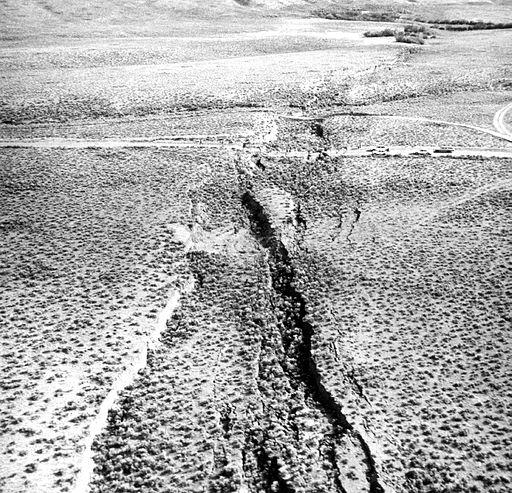

Borah Peak Fault Scarp - public domain imaget: R.E. Wallace, USGS Earthquake Information Bulletin 501, Public domain, via Wikimedia Commons

## Introduction

In this LiveScript, we investigate the possibility of there being a relationship between seasonality and earthquake frequency. We do so by obtaining publicly available USGS data on earthquake events, split the data into events that occur during winter months and those that do not, and then randomly sample several 30 day intervals from each of the split data sets. We count the number of earthquakes that occurred within these intervals. These counts, which we will attempt to model with a Poisson probability distribution, make up our control and experimental data sets. We employ several different types of hypothesis testing in order to determine whether there seems to be a difference in the frequency of earthquakes during winter months in comparison to non-winter months. 

This program has the following objectives:

- Load external data into a MATLAB table.

- Process the data into control and experimental populations cooresponding to earthquakes that occur during winter months and earthquakes that do not.

- Use a Poisson framework randomly sample several 30 day intervals and count the number of earthquakes in the control population that fell within each of the itervals. These counts constitute the control data set. Create an experimental data set by sampling in a similar fashion from the experimetnal population.

- Compute descriptive statistics of the control data. This will include several measures of central tendency, variability, asymmetry, and the importance of outliers.

- Produce several visualizations of the data including histograms and box and whisker plots.

- Fit a probability distribution to the data using parameter estimation and validate the fit of the model by comparing the relative frequency histogram of the data set to a bar graph of the theoretical distribution, comparing the empirical shape parameters of the data to the theoretical shape parameters of the distribution, examining a quantile-quantile plot, and performing Pearson's goodness of fit test.

- Test the null hypothesis that there is no significant difference between the experimental data and the values our theoretical model for the control data leads us to expect.

- Test the null hypothesis that there is no significant difference between the mean of the experimental data and the expected mean of our theoretical distribution (or that there is no significant difference between the means of the control and experimental data sets).

- Test the null hypothesis that there is no significant difference between the variance of the experimental data and the expected variance of our theoretical distribution (or that there is no significant difference between the variances of the control and experimental data sets).

- Use bootstrap sampling methods and perform tests for differences between means based upon the bootstrap samples. 

## Data Collection and Wrangling

Clear all memory, close all figures, and clean out the command line history

clear all; close all; clc;

Since we will be sampling randomly from data sets, choose the seed for the random number generator for reproducibility. Disable this if you want to replicate this experiment multiple times.

rng(1);

Earthquake time, location, and magnitude data is available from the USGS (https://earthquake.usgs.gov/earthquakes/search/). The data set we use can be obtained by searching for earthquakes with a minimum magnitude of 4, located in the conterminous US, and occurring between 2000-1-1 00:00:00 and 2020-12-31-23:59:59 (UTC). Import the data from the USGS csv file into a table, and simplify the time column so that it is represented as datetime data and only reports the daty the earthquake occurred on.

quakeData=readtable("Data/Conterminous_US_Earthquakes2000-2020.csv")

quakeData = 2048×22 table
                time                latitude    longitude    depth    mag     magType    nst     gap      dmin       rms       net            id                    updated                              place                         type         horizontalError    depthError    magError    magNst       status       locationSource    magSource
    ____________________________    ________    _________    _____    ____    _______    ___    _____    _______<

eventTime=cell2mat(quakeData.time);
eventTime=cellstr(eventTime(:,1:10));
quakeData.time=datetime(eventTime);

Split the data set into two tables: winterQuakes (which includes only the earthquakes that occurred in the winter months) and SSSFQuakes (which includes the earthquakes that occurred during the remainding seasons). 

quakeData.season=zeros(size(quakeData.time)); %Winter days (default)
dayofyear=day(quakeData.time,"dayofyear");
quakeData.season(dayofyear>=80 & dayofyear<=171)=1; %Spring days
quakeData.season(dayofyear>=172 & dayofyear<=263)=2; %Summer days
quakeData.season(dayofyear>=264 & dayofyear<=355)=3; %Fall days
winterQuakes=quakeData(quakeData.season==0,:);
SSFQuakes=quakeData(quakeData.season~=0,:);

Randomly sample 40 different intervals of thirty days during the non-winter months. Count the number of earthquakes that occurred within these intervals and record the counts into the control data set.

period=29;

Npts=100;
ControlData=zeros(1,Npts);
for i=1:Npts
    y=randsample(2000:2020,1);
    m=3;
    d=20;
    springStarts=datetime(y,m,d);
    startdate=springStarts+randi(246);
    ControlData(i)=height(SSFQuakes(SSFQuakes.time>=startdate & SSFQuakes.time<=startdate+period,:));
end
ControlData

ControlData =      6     4     3    15     2     4     3    15     4     2     8     3    14     5     9     5     5     9     4     2     3     5     6     5     3     2     8     4     4     4     2     4     6    16     6     5     2     3     2     6     6     6    14     4     7     5     3     6     7    14


Randomly sample 20 different intervals of thirty days during the winter months. Count the number of earthquakes that occurred within these intervals and record the counts into the experimental data set.

Npts=100;
ExperimentalData=zeros(1,Npts);
for i=1:Npts
    y=randsample(2000:2020,1);
    if y==2020
        m=1;
        d=1;
        maxstep=day(datetime(y,3,21),'dayofyear')-29;
    else
        m=randsample([1,12],1);
        if m==1
            d=1;
            maxstep=day(datetime(y,3,21),'dayofyear')-29;
        else
            d=21;
            maxstep=88-29;
        end
    end
    startdate=datetime(y,m,d)+randi(maxstep);
    ExperimentalData(i)=height(winterQuakes(winterQuakes.time>=startdate & winterQuakes.time<=startdate+period,:));
end
ExperimentalData

ExperimentalData =      8     3     4     8     3     8    12     4     7     7     3    17    17    10     6     3    12     3     7     2     4    11     7     9     7     4     3     6     0     5    15     4     4     1     4     3     7    11     6     5    21     6     5    12     9     4     4     3     9    10


## Descriptive Statistics

Summarize the basic, descriptive statistics for the control data set.

ds=STAT121utils.descriptiveStats(ControlData)

ds = struct with fields:
         Mean: 7.1400
       Median: 5
         Mode: 4
          Max: 87
          Min: 0
        Range: 87
       StdDev: 9.3027
     Variance: 86.5404
    Quartiles: [3 5 8.5000]
          IQR: 5.5000
     Skewness: 6.5533
       Bowley: 0.2727
     Kurtosis: 54.9833


## Visualizations

A histogram summarizes the frequencies of each value found in the control data set.

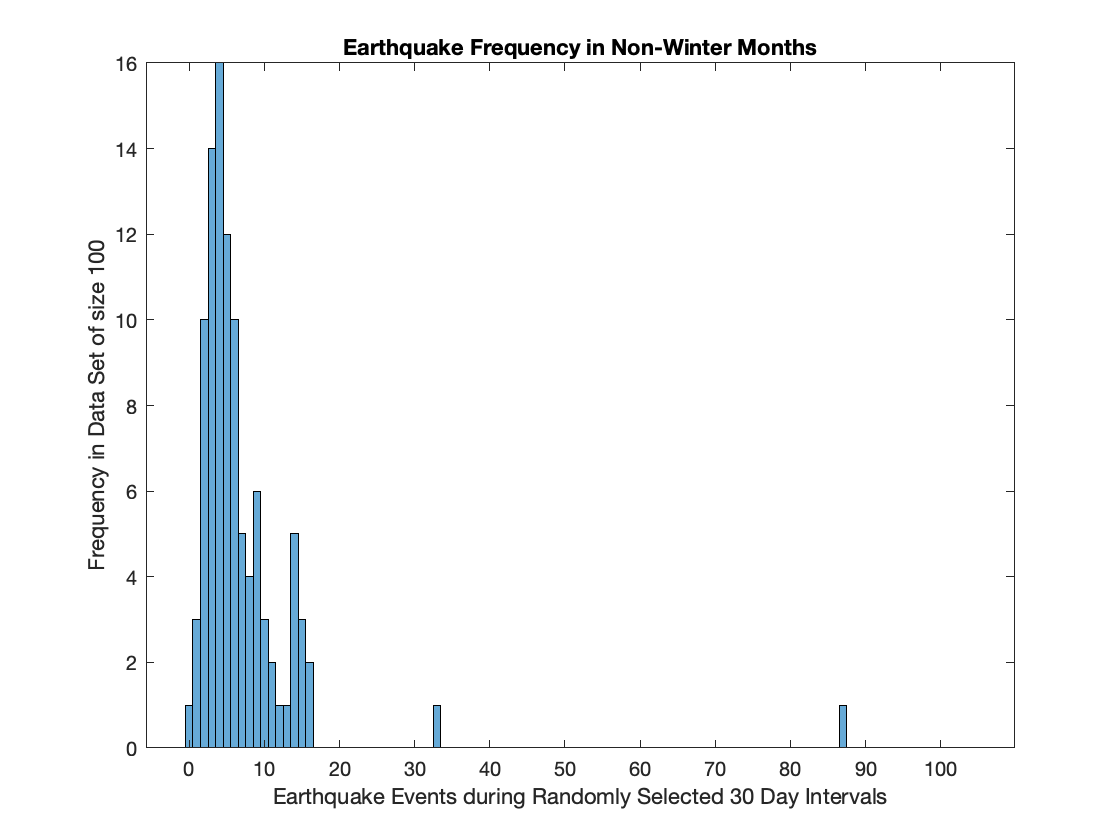

figure(1)
histogram(ControlData,-0.5:1:round(1.2*ds.Max)+0.5)
title("Earthquake Frequency in Non-Winter Months")
xlabel("Earthquake Events during Randomly Selected 30 Day Intervals")
ylabel("Frequency in Data Set of size 100")

A box and whisker plot summarizes the quartiles and outliers of the control data set.

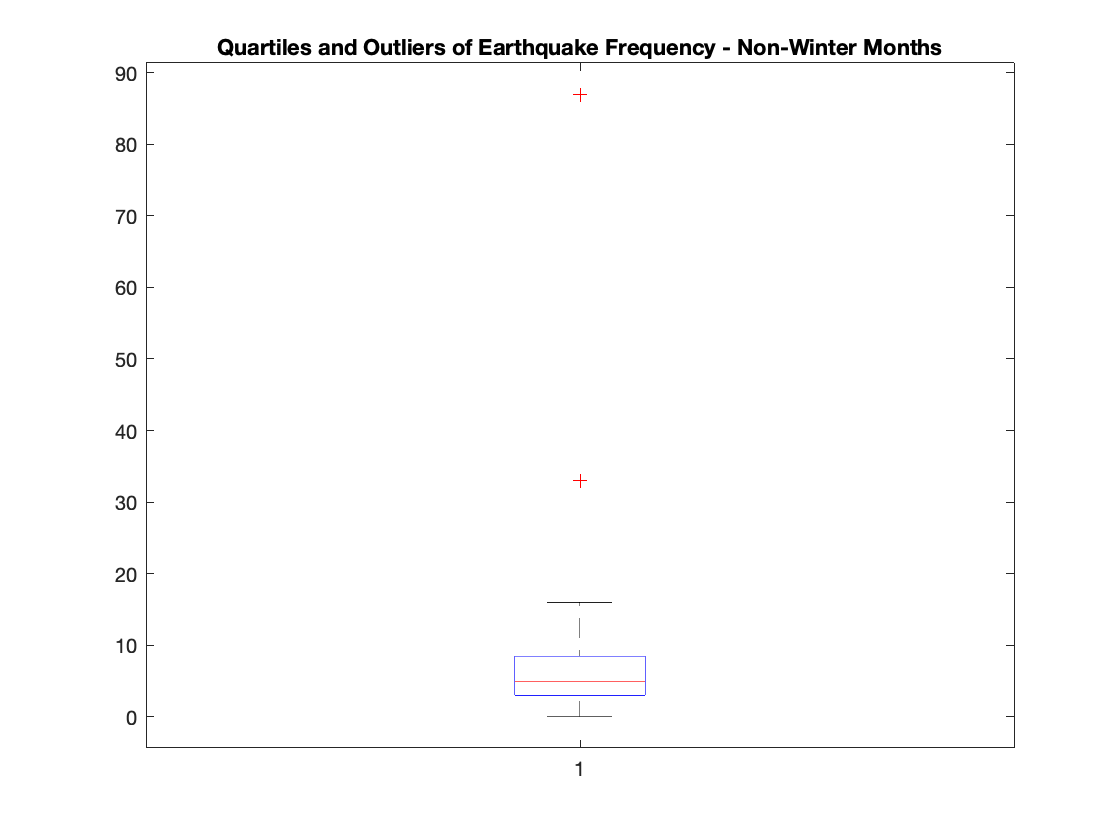

figure(2)
boxplot(ControlData)
title("Quartiles and Outliers of Earthquake Frequency - Non-Winter Months")

## Parameter Estimation

### Maximum Likelihood Estimation

MATLAB has a built in maximum likelihood estimation function (mle). We can use it to perform parameter estimation for many of the common probability distributions. 

lambda=mle(ControlData,"distribution","Poisson")

lambda = 7.1400

### Validation

Create a Poisson distribution object that we calibrate with our value of $\lambda$.

pd=makedist("Poisson","lambda",lambda);

Build the arrays of observed frequencies from the control data set and expected frequencies from the theoretical distribution. Compare these frequencies with a side-by-side bar graph.

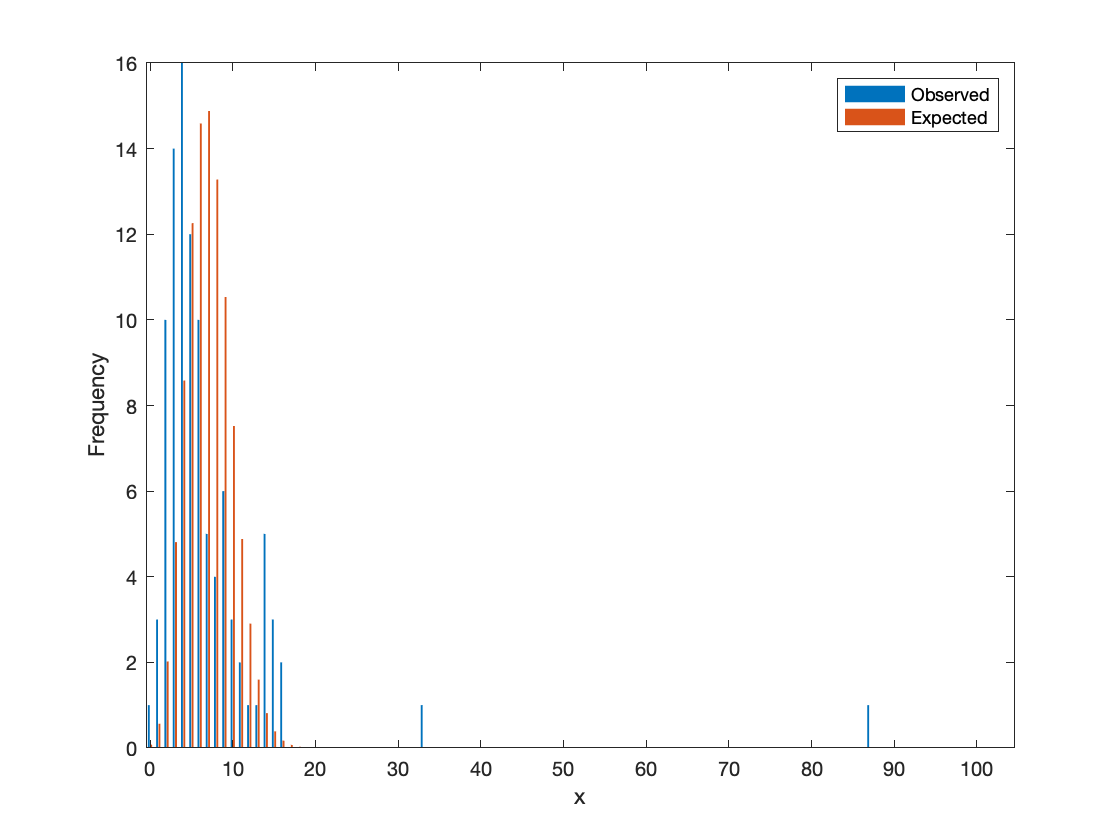

figure(3)
[ObservedFrequencies,ExpectedFrequencies]=STAT121utils.frequencyPlot(ControlData,pd);

The observed data appears to have less symmetry than what the model predicts. Additionally, the observed data appears to have a lower point of central tendency than what the model predicts. We can quantify this somewhat by computing and comparing the empirical and theoretical shape parameters.

shapes=STAT121utils.compareShapeParameters(ControlData,pd)

shapes = 2×4 table
                   MEAN    VARIANCE    SKEWNESS    KURTOSIS
                   ____    ________    ________    ________

    Empirical      7.14     86.54       6.5533      54.983 
    Theoretical    7.14      7.14      0.37424      3.1401 


We can see the means agree (this is a byproduct of our approach to parameter estimation), but that there are substantial differences between the empirical and theoretical variances, skewnesses, and kurtoses.

Construct a quantile-quantile plot that compares the quantiles of the control data set to the corresponding quantiles of the theoretical distribution

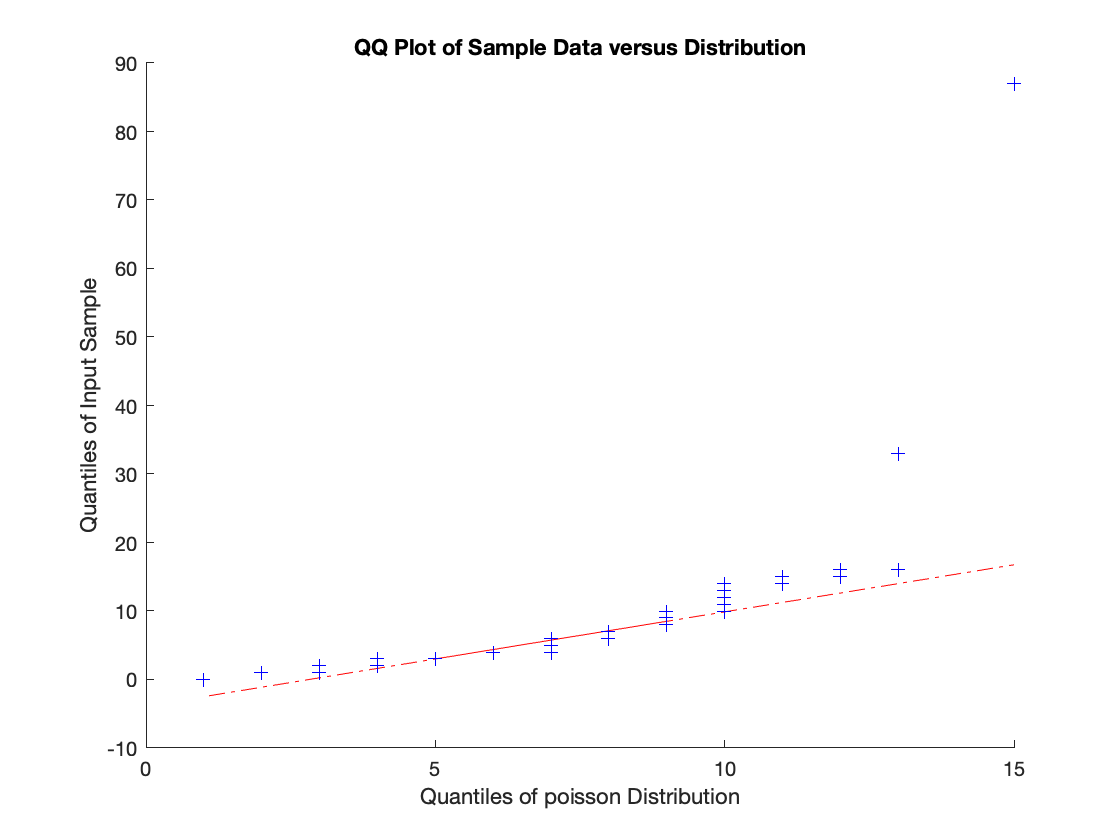

figure(4)
qqplot(ControlData,pd)

The upper quantiles of the data do not appear to agree well with the corresponding theoretical quantiles of the Poisson distribution. 

Finally, perform Pearson's goodness of fit test.

[h,pChi2,stats]=chi2gof(ControlData,'CDF',@pd.cdf,"NBins",20,"NParams",1)

h = 1

pChi2 = 1.1502e-14

stats = struct with fields:
    chi2stat: 59.6207
          df: 1
       edges: [4.9407e-324 4.3500 8.7000 87.0000]
           O: [44 31 25]
           E: [16.0599 55.0066 28.9336]


The goodness of fit test resulted in a small p value. This indicates that we should probably reject the Poisson model for our control data. Since none of our validation techniques were particularly supportive of this model, we should be cautious in relying upon it too heavily in our hypothesis testing efforts.

## Hypothesis Testing

### Fisher's Significance Testing

#### Poisson Test 

We were not able to establish such strong validation for the fit between the Poisson model and our control data. For this reason, the Poissontest for differences between experimental data and behavior predicted by the model may not be our most reliable approach for studying the potential for differences between the experimental data and expected control data behavior. We can still perform the test, however, but treat its results with some skepticism. The null hypothesis for this test is

$H_0$: *We will not observe counts of earthquakes within 30 day intervals during winter months that are significantly different from counts the Poisson model leads us to expect to observe within 30 day intervals during the other months of the year.*

The p values resulting from the Poisson test are computed as follows.:

[pIncreaseDiscrete,pDecreaseDiscrete]=STAT121utils.discreteSignificance(ExperimentalData,pd)

pIncreaseDiscrete =     0.4221    0.9733    0.9252    0.4221    0.9733    0.4221    0.0599    0.9252    0.5709    0.5709    0.9733    0.0012    0.0012    0.1840    0.7168    0.9733    0.0599    0.9733    0.5709    0.9935    0.9252    0.1088    0.5709    0.2893    0.5709    0.9252    0.9733    0.7168    1.0000    0.8394    0.0068    0.9252    0.9252    0.9992    0.9252    0.9733    0.5709    0.1088    0.7168    0.8394    0.0000    0.7168    0.8394    0.0599    0.2893    0.9252    0.9252    0.9733    0.2893    0.1840


pDecreaseDiscrete =     0.7107    0.0748    0.1606    0.7107    0.0748    0.7107    0.9691    0.1606    0.5779    0.5779    0.0748    0.9995    0.9995    0.8912    0.4291    0.0748    0.9691    0.0748    0.5779    0.0267    0.1606    0.9401    0.5779    0.8160    0.5779    0.1606    0.0748    0.4291    0.0008    0.2832    0.9971    0.1606    0.1606    0.0065    0.1606    0.0748    0.5779    0.9401    0.4291    0.2832    1.0000    0.4291    0.2832    0.9691    0.8160    0.1606    0.1606    0.0748    0.8160    0.8912


sum(pIncreaseDiscrete<0.05)

ans = 10

sum(pDecreaseDiscrete<0.05)

ans = 10

Here, about 1-2% of the p values from both the test for an increase and decrease fall below 5%. This s not a majority, and not a surprising number of significant results. Thus, the Poisson test does not provide evidence for rejecting the null hypothesis.

#### One Sample T-Test

We could conduct a one sample t test for differences between the mean of the experimental set and the theoretical mean predicted by the Poisson distribution. Unfortunately, the poor fit between the Poisson model and the control data weakens the validity of this test because we can't really say we have a firm grasp of the theoretical mean of the space our control data was sampled from. However, we'll perform the test anyway. The null hypothesis for this test is

$H_0$*: There is no significant difference between the mean of the experimental data set and the theoretical mean predicted by the Poisson distribution. *

This test can be performed as follows:

[h,pt,ci,stats]=ttest(ExperimentalData,pd.mean)

h = 0

pt = 0.1245

ci =     5.6804    7.3196


stats = struct with fields:
    tstat: -1.5495
       df: 99
       sd: 4.1304


The p value (pt) for this test is much larger than 5%. This provides insufficient evidence for rejecting the null hypothesis that the theoretical mean and mean of the experimental sample are the same. The ttest function also provides us with a 95% confidence interval that establishes the location of the true mean for the population that the experimental data is taken from. However, we should be cautious in placing our faith in the results of this test since its use relies upon our knowledge of a theoretical distribution for our control data.

#### Two Sample T Test

Alternatively, we could address the slightly different task of determining if there is a difference between the means of the control and experimental data sets by conducting the two sample t test. Before doing so, it is worth investigating the similarity between the control and experimental variances, because this can impact how we design our two sample T test. There are two approaches we can follow:

First, since we know the Poisson distribution fits our control data well, we are not overly justified in conducting the $\chi^2$ test for differences between the sample variance of our experimental data set and our theoretical variance predicted by the Poisson distribution. However, we'll perform it anyway The null hypothesis for the $\chi^2$ test is

$H_0$*: There is no significant difference between the variance of the experimental data and the theoretical variance predicted by the Poisson distribution.*

and we may perform the test as follows:

[h,pvar,ci,stats]=vartest(ExperimentalData,pd.var)

h = 1

pvar = 5.7110e-13

ci =    13.1520   23.0231


stats = struct with fields:
    chisqstat: 236.5546
           df: 99


We can se that the p vlaue is small enough to reject the null hypothesis that there is no difference between the variances. The $\chi^2$ test also supplies a 95% confidence interval for the true variance of the population the experimental data was sampled from. However, this test also relies upon knowledge of the theoretical distribution for our control data, so we should place limited faith in its conclusion.

Since we have been unable to establish such a good fit between our Poisson model and our control data, we can alternatively investigate similarities between the variances of the populations the experimental and control data sets were sampled from by conducting the F test. This is probably our best option for exploring differences in the variability between our control and experimental populations, so we'll perform it. The null hypothesis for this test is

$H_0$*: There is no significant difference between the variance of the experimental data set and the variance of the control data set. *

We perform the test as follows:

[h,pvar2,ci,stats]=vartest2(ExperimentalData,ControlData)

h = 1

pvar2 = 1.2065e-14

ci =     0.1313    0.2901


stats = struct with fields:
    fstat: 0.1952
      df1: 99
      df2: 99


Again, the p value is quite small, so we have strong evidence for rejecting the null hypothesis that there is no difference between the variance. The F test also supplies a 95% confidence interval for the true ratio between the variances of the experimental and control populations.

Since we can be fairly certain that there is a real difference between our control and experimental variances, we should drop the assumption of equal variances when performing the two sample t test. 

The null hypothesis for the two sample t test (without an assumption of equal variances between the experimental and control samples) is 

$H_0$*: There is no significant difference between the means of the experimental and control data sets.* 

This test bypasses the need of knowing that the Poisson distribution is the model for our original counts of test subjects in our sample with heart disease and having access to the theoretical mean of that distribution. We simply treat our control and experimental data sets as two independent samples (with potentially different sample variances) and test for equality of the two sample means. This makes it an appropriate choice of a hypothesis test for determining differences between our experimental and control measurements since we were unable to achieve a strong fit between our Poisson model and the control data. We may perform this test as follows:

[h,pt2,ci,stats]=ttest2(ExperimentalData,ControlData,'Vartype',"unequal")

h = 0

pt2 = 0.5323

ci =    -2.6613    1.3813


stats = struct with fields:
    tstat: -0.6261
       df: 136.2255
       sd: [4.1304 9.3496]


Again,the p value (pt2) from the two sample t test is not particularly small. Therefore it produces insufficient evidence for rejecting the null hypothesis that the means of the experimental and control samples are the same. The ttest2 function also provides us with a 95% confidence interval that establishes the location of the difference between the true means for the populations that the experimental and control data is taken from. When we compute the actual difference of the sample means:

mean(ExperimentalData)-ds.Mean

ans = -0.6400

we see that it indeed falls within the confidence interval. This is another indicator that there isn't much difference between the experimental and control means.

### Bootstrap Confidence Interval

Simulate 2000 samples of 40 data points from the control data set and compute their means. This set of means is a bootstrap data set.

B=2000;
bootstrapMeans=bootstrp(B,@mean,ControlData);

Compute a 95%, two-tailed confidence interval from the bootstrap data set by locating its 2.5 and 97.5 percentiles. Determine where the mean of the experimental data set falls relative to the confidence interval.

CI=quantile(bootstrapMeans,[0.025 0.975])

CI =     5.5950    9.2850


Me=mean(ExperimentalData)

Me = 6.5000

Visualize the confidence interval and experimental mean on top of the bootstrap data set.

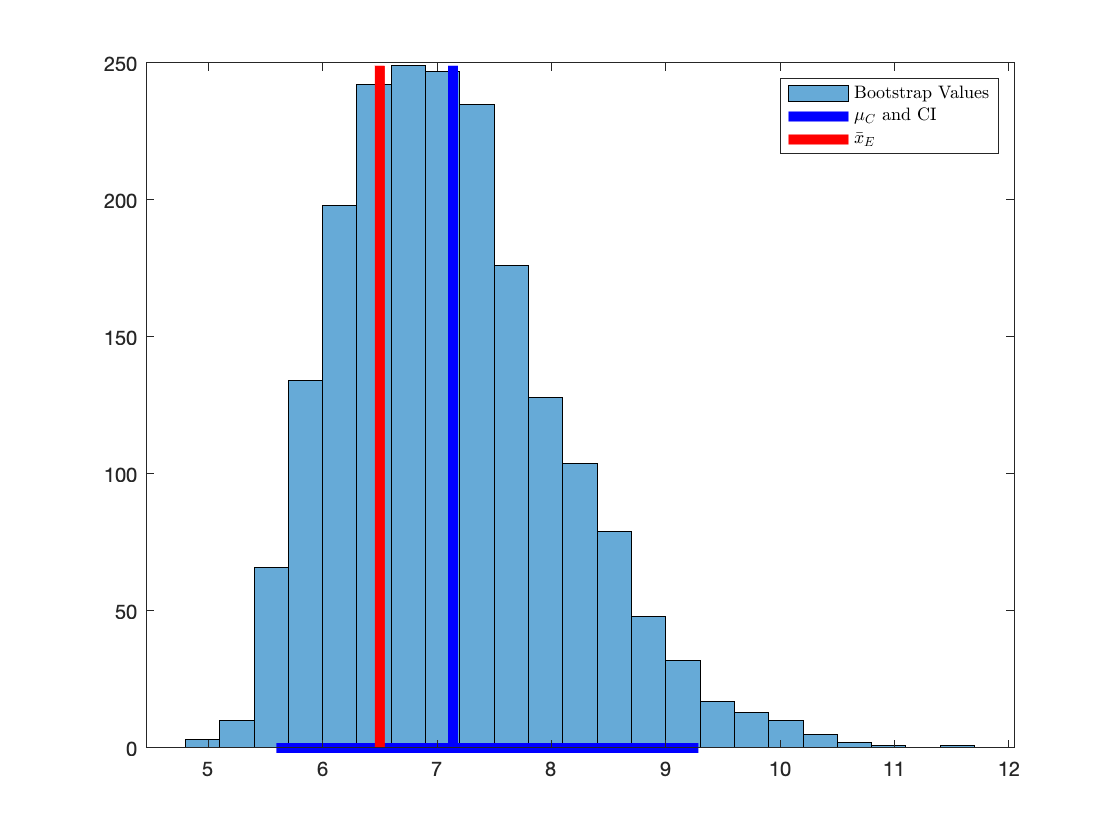

figure(5)
h=histogram(bootstrapMeans);
hold on
plot(CI,[0,0],'b','LineWidth',5)
plot([Me,Me],[0,max(h.BinCounts)],'r','LineWidth',5)
plot([pd.mean,pd.mean],[0,max(h.BinCounts)],'b','LineWidth',5)
legend('Bootstrap Values','$\mu_C$ and CI', '$\bar{x}_E$','interpreter','Latex')
hold off

We can see that the mean of our experimental data set falls well inside the bootstrap confidence interval. This is an indication that the mean of our experimental data set is not terribly different from what we expect to see in typical control data.

#### Bootstrap Two Sample Test

We can also create a bootstrap sample from our experimental data set. This has the potential to give us a better picture of what might happen should we repeat our experiment multiple times. 

Create 2000 bootstrap samples from both the control and experimental data sets. The size of each sample taken from the control data set should mirror the size of the control data set. The size of each sample taken from the experimental data set should mirror the size of the experimental data set. For each sample, track the sample means and sample standard deviations as well as the two sample t statistic (that makes no assumption about similarity between control and sample variances).

B=2000;

Nc=length(ControlData);
Ne=length(ExperimentalData);
xbar=mean(ControlData);
ybar=mean(ExperimentalData);
zbar=mean([ControlData ExperimentalData]);

statsc=bootstrp(B,@(x)[mean(x),std(x)],ControlData-xbar+zbar);
statse=bootstrp(B,@(x)[mean(x),std(x)],ExperimentalData-ybar+zbar);
Mc=statsc(:,1);
Sc=statsc(:,2);
Me=statse(:,1);
Se=statse(:,2);
t=(Me-Mc);
t=t./sqrt((Se.^2/Ne)+(Sc.^2/Nc));


Compare the histograms of the two bootstrap data sets.

figure(6)
CIc=quantile(Mc+xbar-zbar,[0.025,0.975])

CIc =     5.6600    9.3700


CIe=quantile(Me+ybar-zbar,[0.025,0.975])

CIe =     5.7150    7.3000


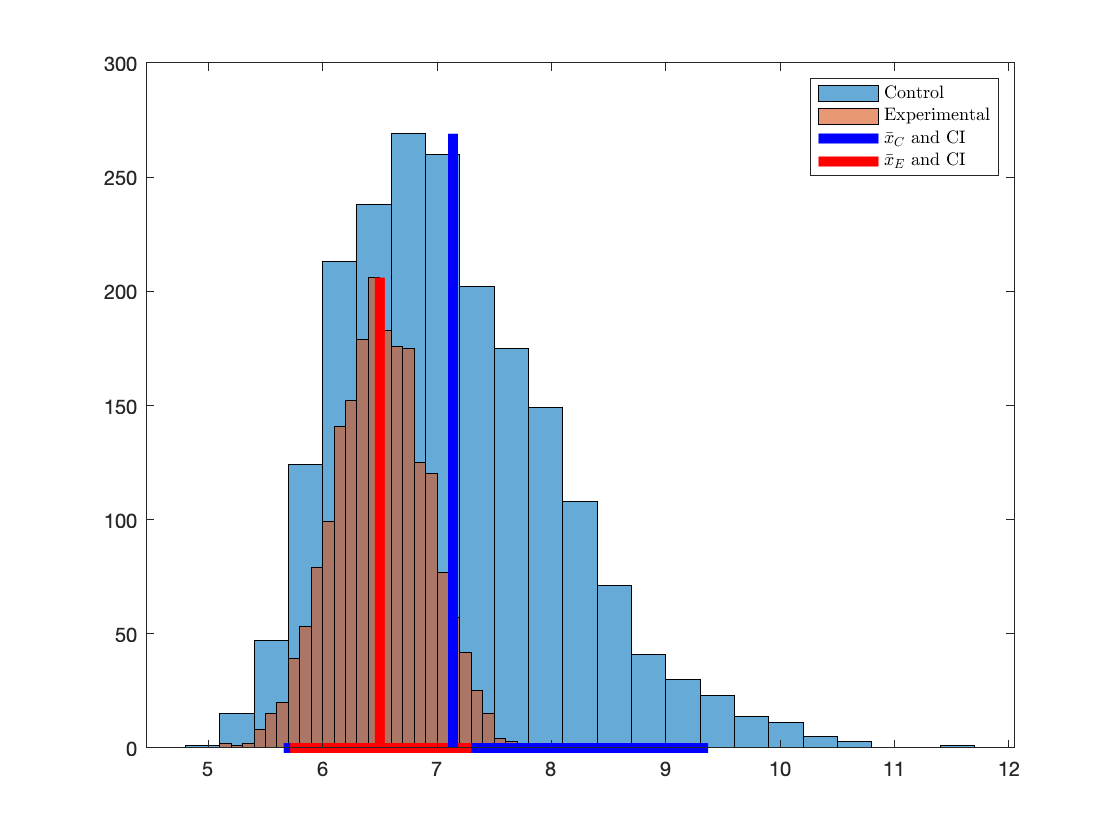


hc=histogram(Mc+xbar-zbar);
hold on 
he=histogram(Me+ybar-zbar);
plot(CIc,[0,0],'b','LineWidth',5)
plot(CIe,[0,0],'r','LineWidth',5)
plot([xbar xbar],[0,max(hc.BinCounts)],'b',"LineWidth",5)
plot([ybar ybar],[0,max(he.BinCounts)],'r',"LineWidth",5)
legend('Control','Experimental','$\bar{x}_C$ and CI', '$\bar{x}_E$ and CI','interpreter','latex')

hold off

There appears to be a great deal of overlap between the bootstrap distributions as well as the two confidence intervals. Additionally, the two sample means appear to be entirely contained within both confidence intervals. All of this indicates that there is little difference between the two sample means, but we should determine this using more quantitative methods as well. Since we have a bootstrapped data set of two-sample t statistics, we can perform the analog of a two sample t test by computing the Achieved Significance Level (ASL) for testing whether the t statistic ($t_0$) for the experimental and control samples is significantly different from what we expect of t statistics computed from bootstrap samples that have been shifted to share a common mean. The ASL represents the percentage of bootstrapped t statistics for which $t\ge t_0$. We can use it lieu of the p-value from the two sample t-test.

t0=stats.tstat;
ASLboot=sum(t>=t0)/B

ASLboot = 0.7795

This value is not small enough to quantitatively suggest that there is a significant difference between the two sample means.